## **Lab 10**

format long e

**Table**

x = [1.0 1.1 1.3 1.5 1.9 2.1];
y = [1.84 1.96 2.21 2.45 2.94 3.18]';

**Setting Up Matrices**

% setup equation matrices
A_linear = polymat(x, 1);
A_quad = polymat(x, 2);
A_cube = polymat(x, 3);

% transpose A
AT_linear = transpose(A_linear);
AT_quad = transpose(A_quad);
AT_cube = transpose(A_cube);

% (transpose A) * vec_b
BT_linear = AT_linear*y;
BT_quad = AT_quad*y;
BT_cube = AT_cube*y;

x_linear = mldivide(AT_linear*A_linear, BT_linear);
x_quad = mldivide(AT_quad*A_quad, BT_quad);
x_cube = mldivide(AT_cube*A_cube, BT_cube);

**Plots**

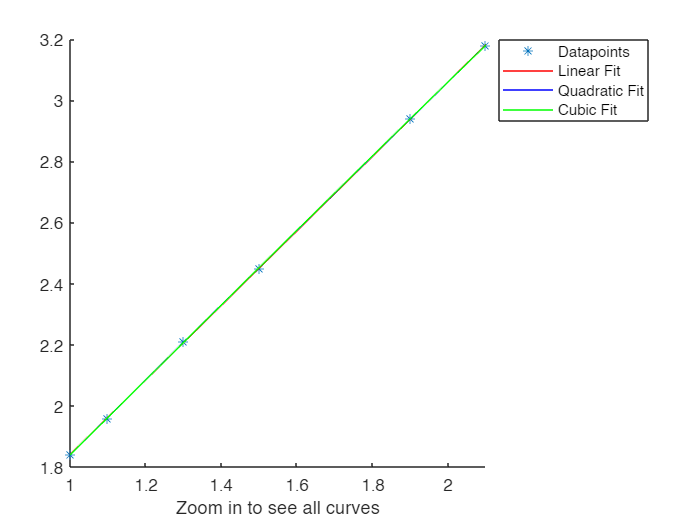

dom = linspace(0, 3, 1000);

hold on;
plot(x, y, '*', dom, vector2val(x_linear, dom), 'r-');
plot(dom, vector2val(x_quad, dom), 'b-');
plot(dom, vector2val(x_cube, dom), 'g-');
xlim([1 2.1])
xlabel('Zoom in to see all curves') % using this as a caption
hold off;

legend("Datapoints", "Linear Fit", "Quadratic Fit", "Cubic Fit", 'Location', 'northeastoutside');

**Observations**

The bext approximation is the linear fit. When we look at the data it is evident the relation seems to be near linear as there is about a .12 unit change in y when there is a .1 change in x. Given that the data is linear it seems higher degree models have a harder time fitting the data. 

This seems to true when we look at ${\bar{x} }^*$ for the quadratic and cubic fit. For the quadratic curve the quadratic constant is $\approx -0\ldotp 01$. For the cubic fit the quadratic constant and cubic constant are $\approx 0\ldotp 03$ and $\approx -0\ldotp 01$ respectively. In both cases (quadratic and cubic) the linear constant seems to be significantly larger.

With such small constants the higher degree models seem to emulate linear behavior near the dataset implying that the linear model *may* be the best fit. 

**Setting Up Matrices - Procedures**

function A = polymat(x, n)
   % x : data points (row)
   % n : degree
    
   if n < 1
       fprintf("degree error")
       return;
   end

   A = zeros(length(x), n + 1);
   
   for i = 1:length(x)
       A(i, 1) = 1; % a_0
       for j = 2:n + 1
           A(i, j) = x(i).^(j-1); 
       end
   end
end

% [a b c] -> a + bx + cxx
function val = vector2val(vec, point)
    val = vec(1);
    for i = 2:height(vec)
        val = val + (vec(i) .* (point.^(i-1)));
    end
end